addpath ./matlab_functions_mcxyzn
addpath ./matlab_functions_mcml

This is a Matlab Live Script, that visualises the implementation of the parameter estimation algorithm, that is proposed by Moco. The goal was to simulate the optical properties of finger skin tissue with monte carlo method. Therefore the programs MCML and mcxyzn where used. 

MCML is a program, that can simulate multiple tissue layers with mclm. It needs a input file, where the properties of the layers are given:   

n:         refractive index

mua:    absorption coefficient

mus:    scattering coefficient  

g:         anisotropy

d:         layer thickness

These coefficients where computed using Mocos proposed method. This is using the absorption coefficients of Blood, Water and Fat and estimating the concentration of these Parts per Layer. mcml has a discrete coordinate system with cylindrical coordinates, so the thickness of the layers has to fit into the grid elements. 

n, mus, g and d were given in the moco paper.

mus was taken from chatterje et al (2020). The coeffiecients (for each wavelength in nm) are saved in the following table:

lib =  load('spectralLIBv3.mat');
fn = fieldnames(lib);
for i = 1: numel(fn)
    lib.(fn{i}) = lib.(fn{i}).';
end
t = struct2table(lib)

t = 8×5 table
    muadeoxy    muafat    muaoxy    muawater    nmLIB
    ________    ______    ______    ________    _____

      82.9       0.76     170.5     0.000247     470 
     178.2       0.73     209.1      0.00032     530 
      16.4       0.65       1.5       0.0032     660 
       7.3        1.1         3     0.019858     770 
       4.5       1.38         4      0.26737     810 
       4.3       1.44       6.5         0.36     940 
       2.8       0.16       6.1         0.52    1020 
       2.2       1.57       4.9        0.885    1050 


Tissue.m is a class, that represents this Tissue with the properties but also with the calculation using a Lib for the absorption coefficients for blood, water and fat.  

These simulations are performed for the given different wavelenght of light and therefore the tissue properties have to be calculated for each wavelength and this is dependent on the absorption coefficients. 

Here is an overview on the results of the calculation:

n,g and d are fixed values given by moco. mus is also given by moco for each layer and is further specified by the wavelength. 

Only mua is more difficult to determine. Here, the calculation depends on the layer, the wavelength but also the concentration of arterial and venious blood, the oxygen concentration in the blood and further factors. For a listing of the whole calculation, see Tissue.m. Because of these different conditions, some cases were distiguished. In one case, the absorbtion coefficient was calculated for Tissue in the systolic state and the diastolic state. Furthermore it was distinguished between compressed skin and skin without compression (normal). This means with 8 different wavelength, there are 32 simulations to be prepared. Chatterjee also listed absorption coefficients for different skin layers, but defined the layers slightly different. As the definition is most simmilar to the normal diastolic skin by moco (still moco defined a small layer of upper plexus as third layer, which is not included in chatterjees model), here is a comparison between those two  types:

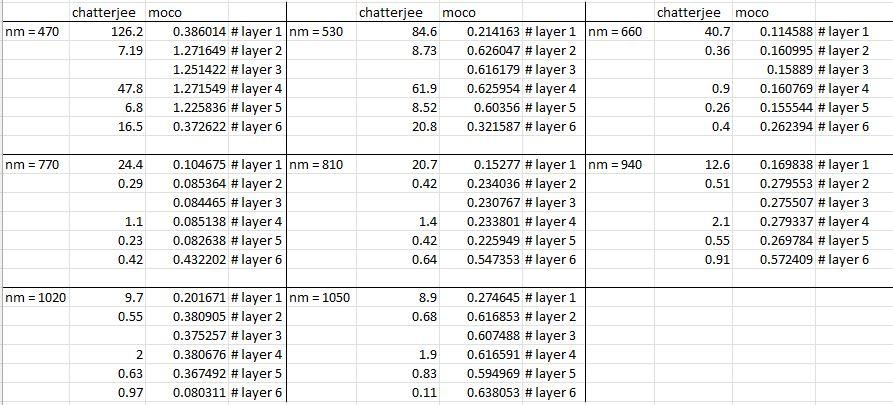

For further interests one can look up every coeficient in the folder data_files/inputs 

To get an impression of the frequency dependent .... of the absorption coefficients, this function generates a plot of the absorption coefficients for normal diastolic skin and a p (pulsation increase of blood volume) of 0.3:

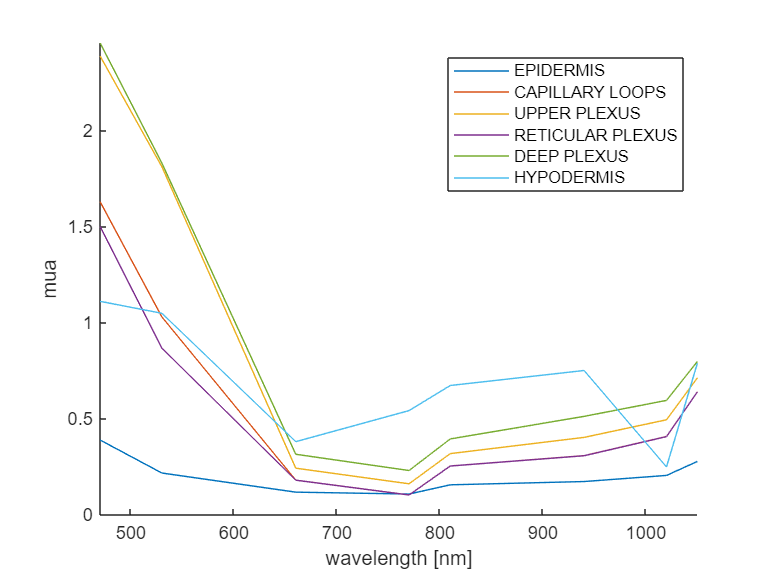

visualize_tissue('diastolic','normal',0.3)

The simulation for each wavelength in the Lib can be runned by 

DOSIM = 0;
if DOSIM
    launch_simulation_mcml()
end

 This will take a while to compute. It takes the calculated coefficients and writes them to a .mci file and launches the simulation with this file as input. The simulation is performed with 10e9 photons and a grid with 1000 grid elements in radial direction and a grid step size of 0.001 cm in z direction which results in 773 grid elements for normal skin. 

To get an impression of how the simulated tissue behaves, one can calculate the penetration depth as the depth, where 63.2% of the photones are still not absorbed. This means, that the fluence at this point is at 63.2% of the fluence at the surface. 

To do this, call read_fluence_mcml(). The parameter of the function is wether the Fluence graph of each wavelength should be plotted (1) or not (0).

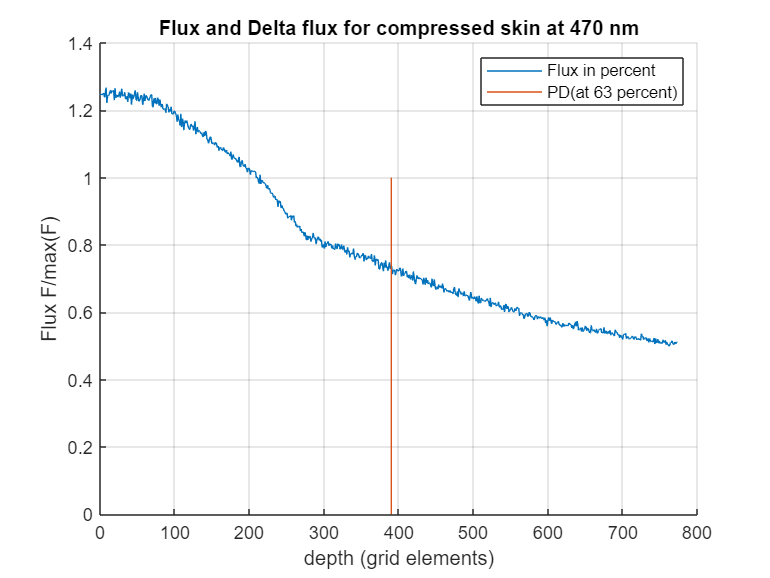

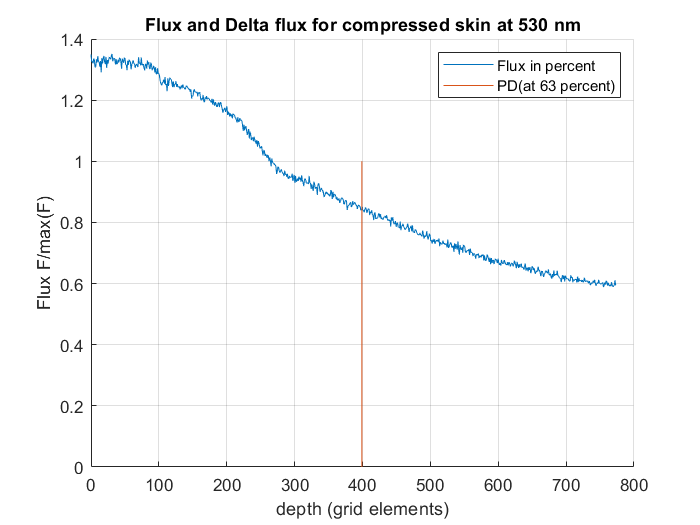

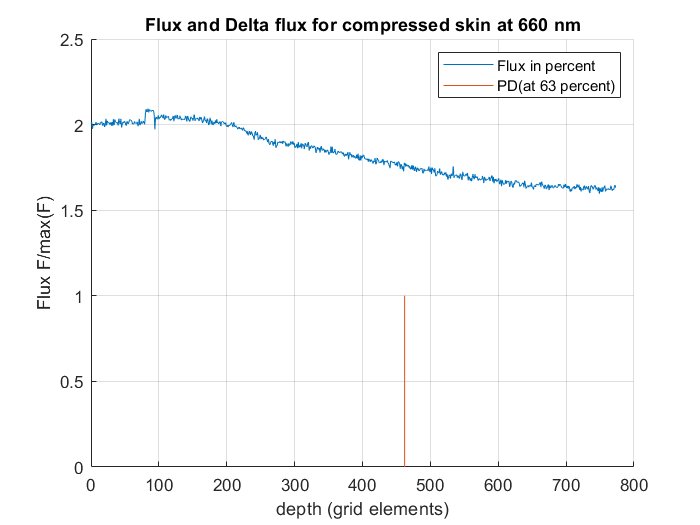

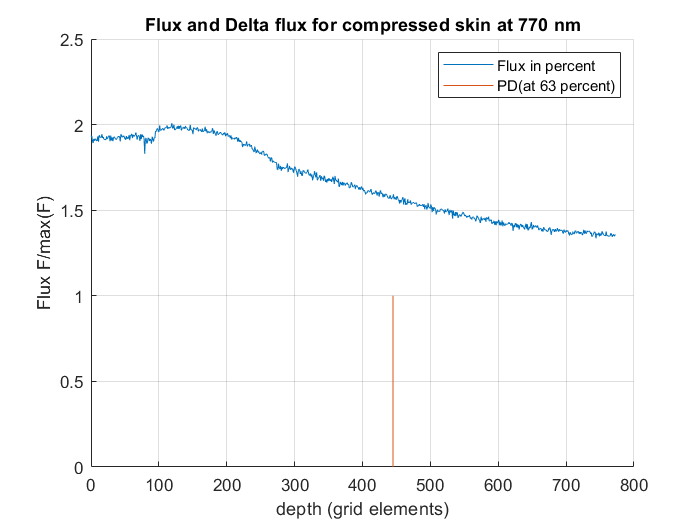

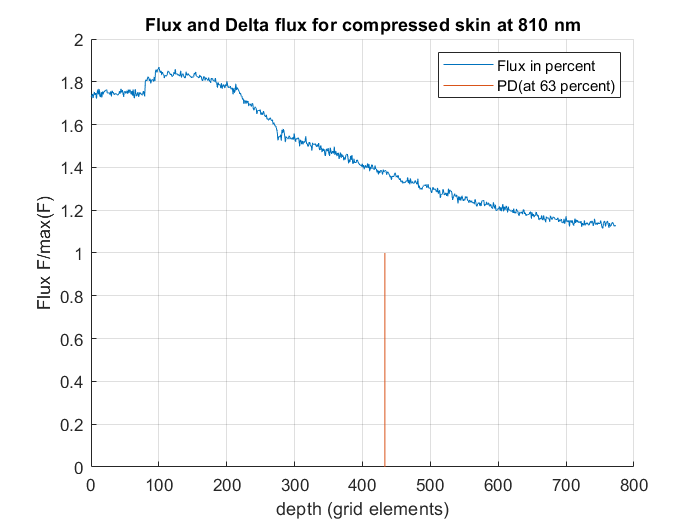

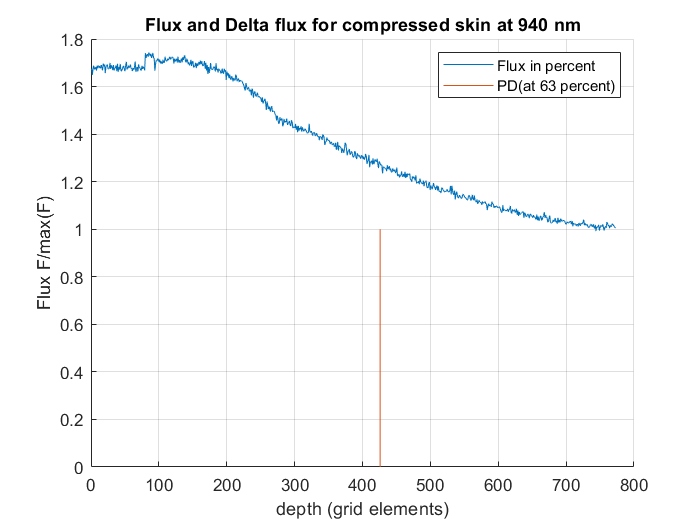

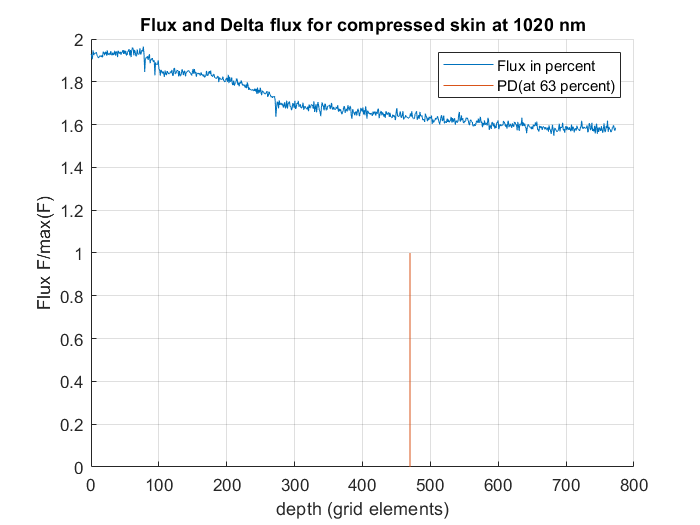

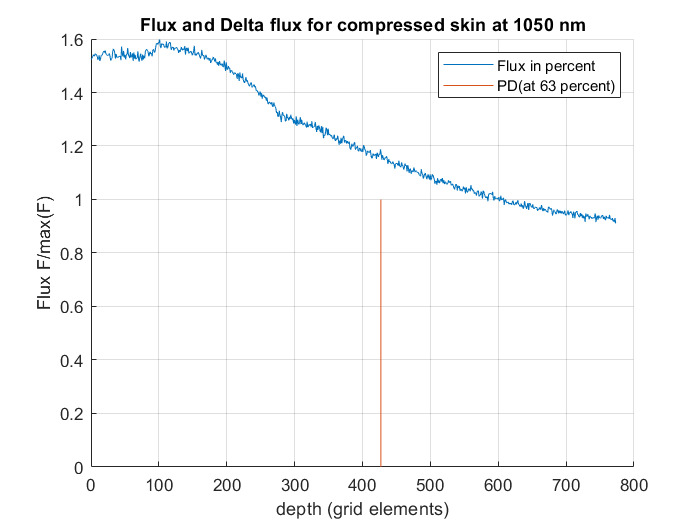

read_fluence_mcml(1)

mcxyzn does the same as MCML, but it uses Voxels where each Voxel has these properties instead of Layers, so layer thickness has to be transposed into number of Voxels.

This simulation for each wavelenth in the Lib can be runned by 

if DOSIM
    launch_simulation_mcxyzn()
end

This will take a while to compute. Here, only 200 grid elements in x and y direction were used and the same amount of grid elements in z direction as for mcml

To get an impression of how the simulated tissue behaves, one can calculate the penetration depth as the depth, where 63.2% of the photones are still not absorbed. This means, that the fluence at this point is at 63.2% of the fluence at the surface. 

Elapsed time is 3.011547 seconds.


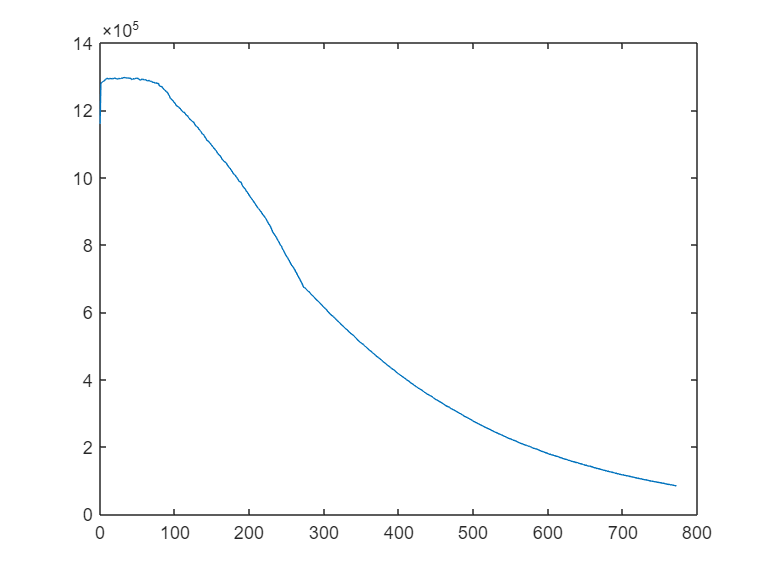

Elapsed time is 3.585256 seconds.


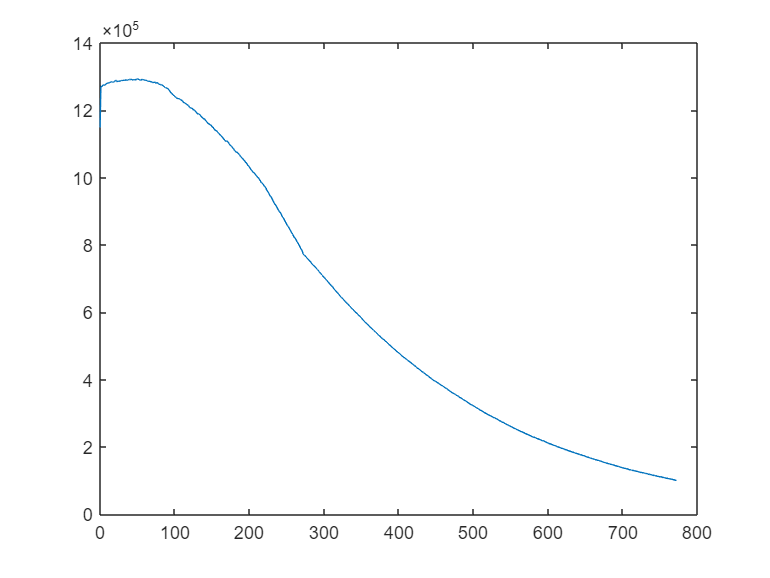

Elapsed time is 3.112980 seconds.


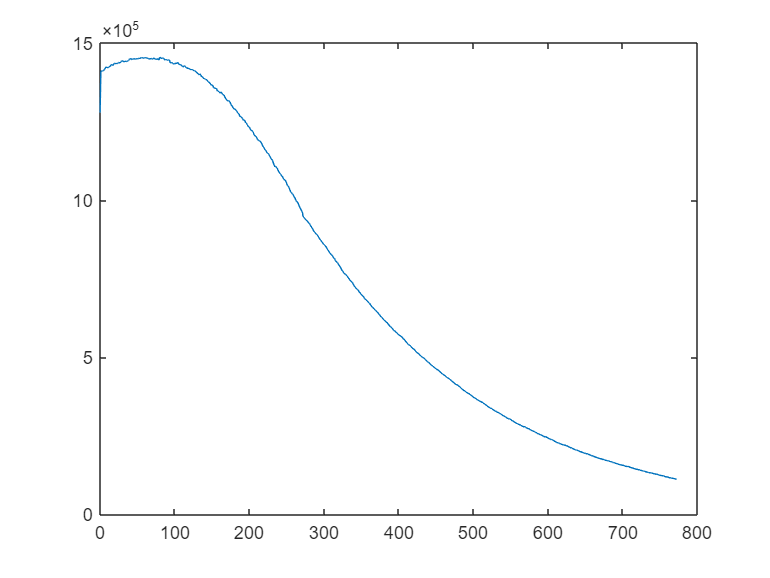

Elapsed time is 2.609295 seconds.


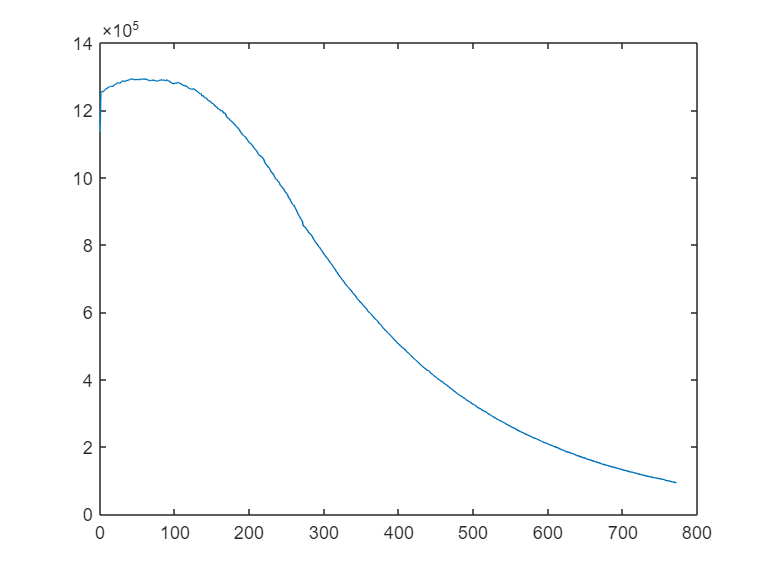

Elapsed time is 1.923569 seconds.


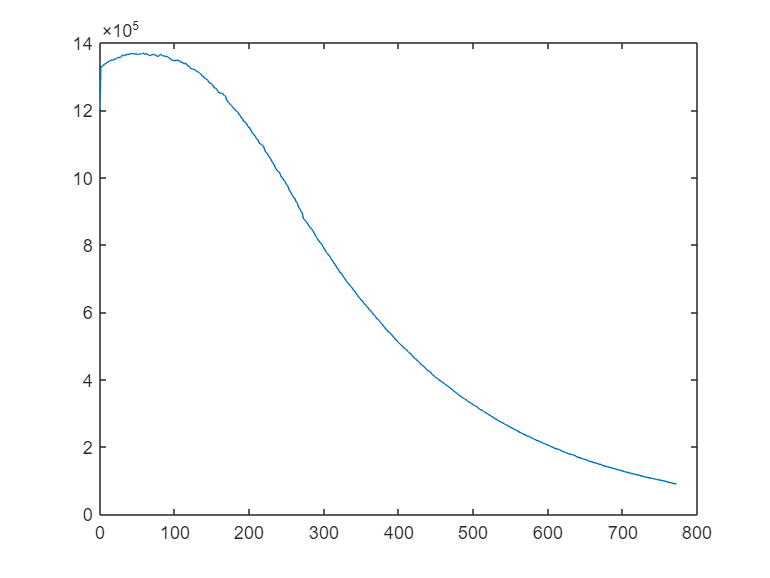

Elapsed time is 1.880065 seconds.


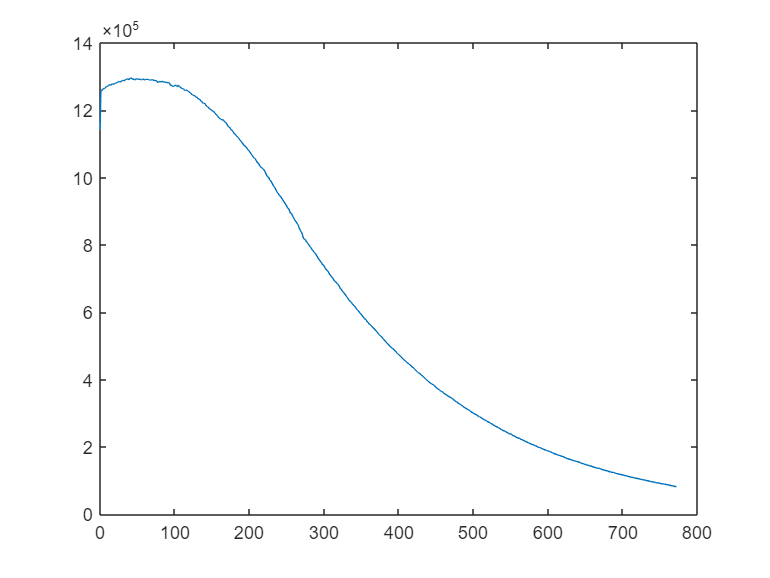

Elapsed time is 1.564251 seconds.


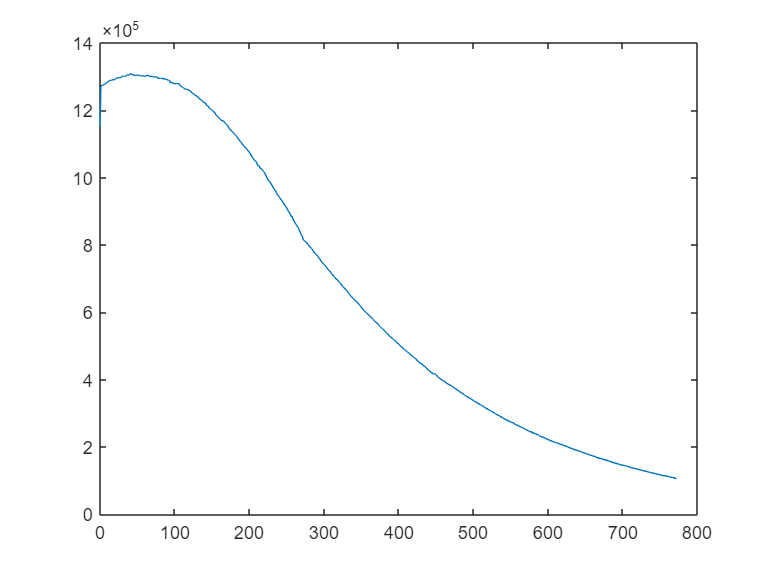

Elapsed time is 3.089913 seconds.


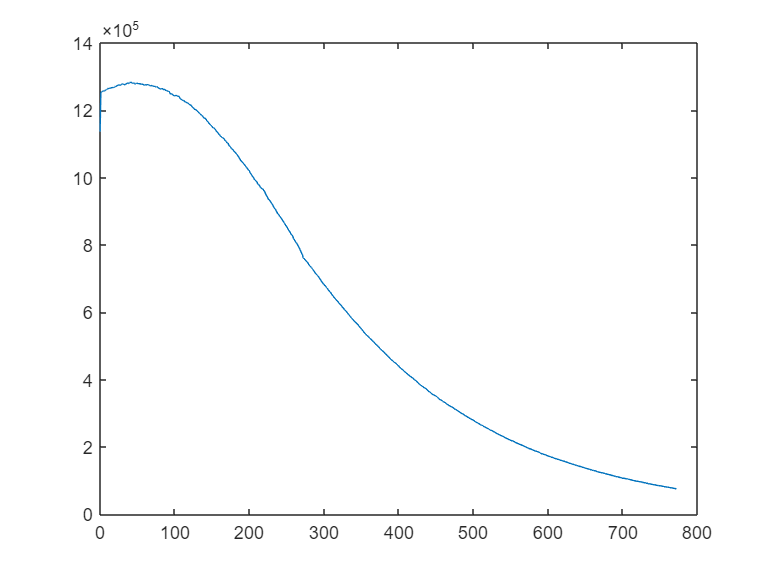

Elapsed time is 1.405661 seconds.


Elapsed time is 1.474587 seconds.


Elapsed time is 1.295106 seconds.


Elapsed time is 1.275212 seconds.


Elapsed time is 1.357965 seconds.


Elapsed time is 1.299338 seconds.


Elapsed time is 1.247911 seconds.


Elapsed time is 1.265131 seconds.


read_fluence_mcxyzn(1,0)

For Comparison, the Penetraion Depth for each wavelength with Chatterjees coefficients simulated by mcml looks like this.

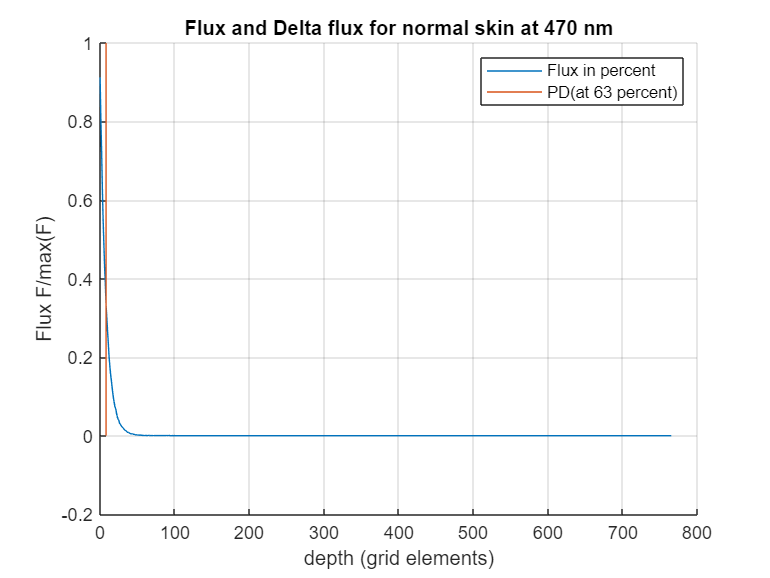

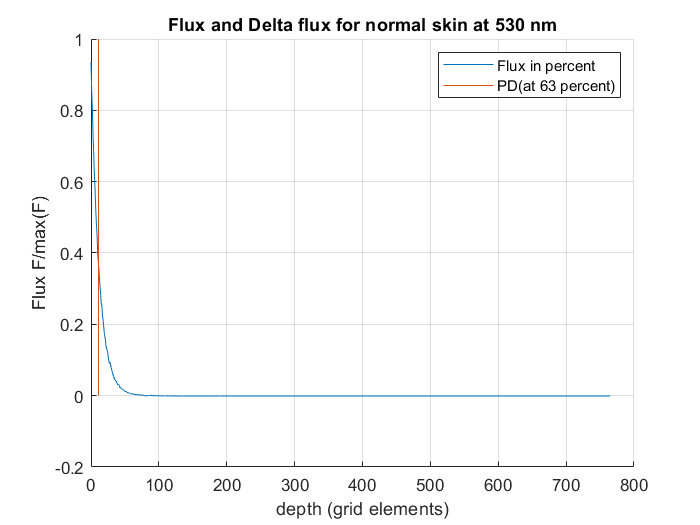

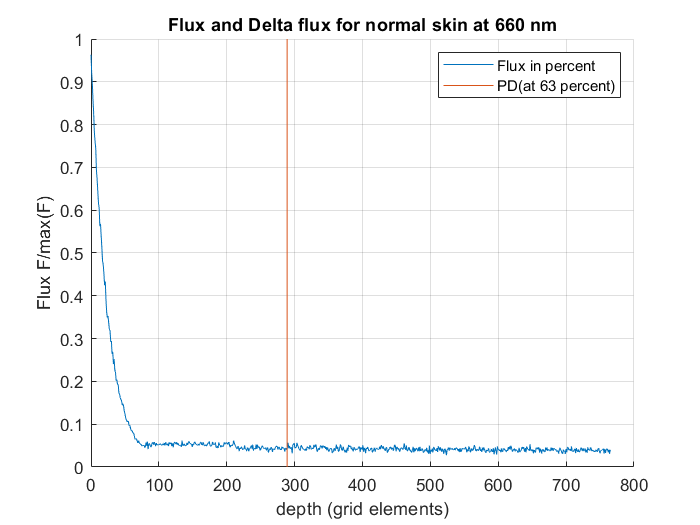

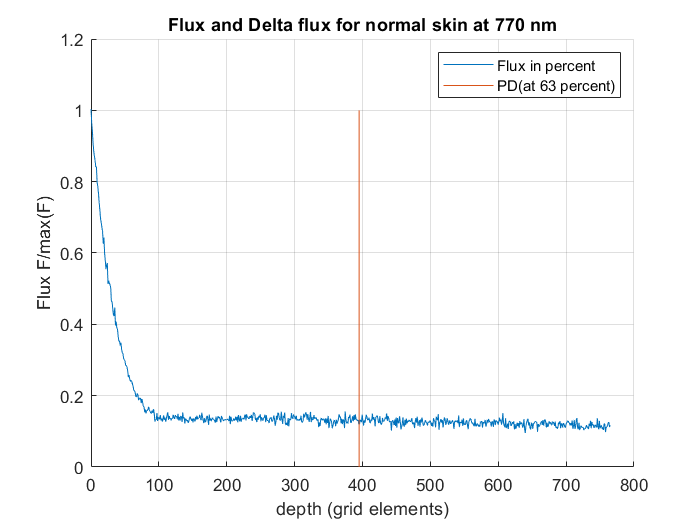

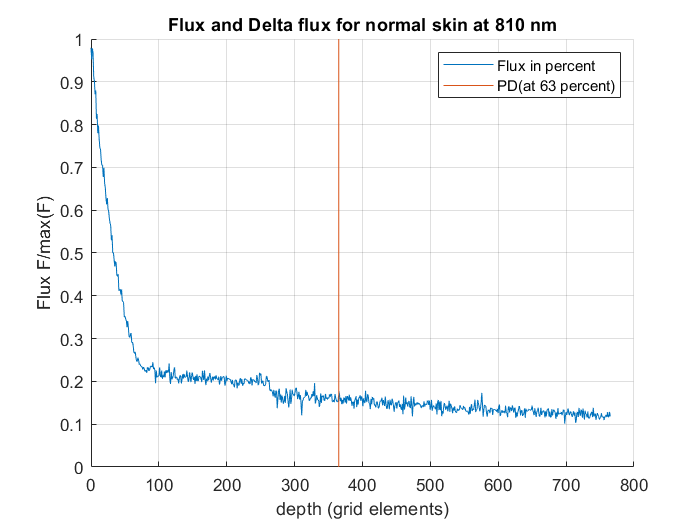

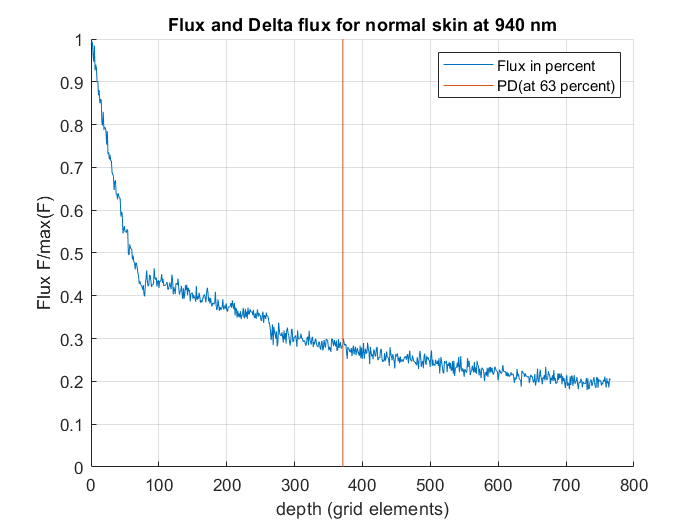

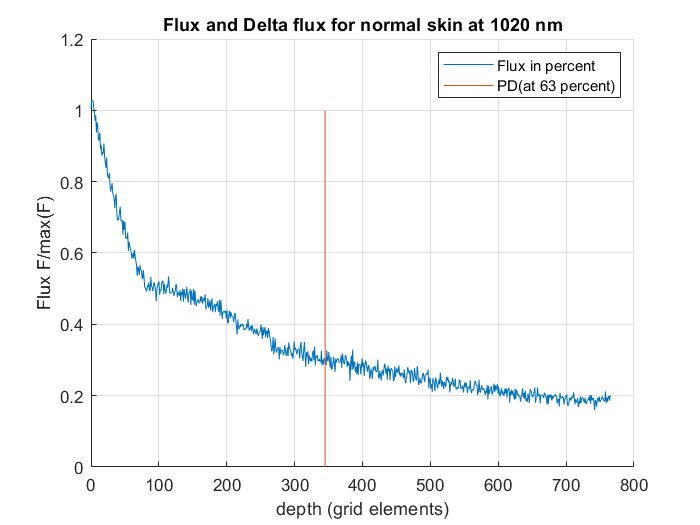

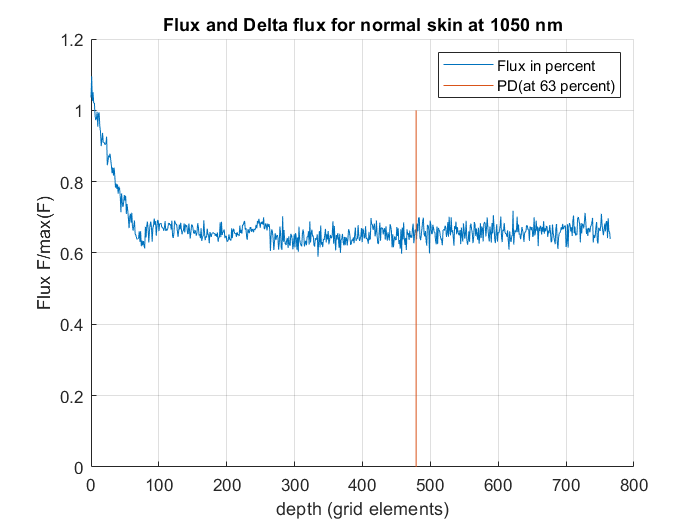

read_fluence_mcml_chatterjee(1)

if DOSIM
    muaoxy = load('spectralLIBv3.mat', 'muaoxy');
    tissue_type.mua = muaoxy.muaoxy;
    launch_simulation_mcxyzn(0.3, 50/2, [200,200,800]/2, tissue_type);
end

Elapsed time is 3.164156 seconds.


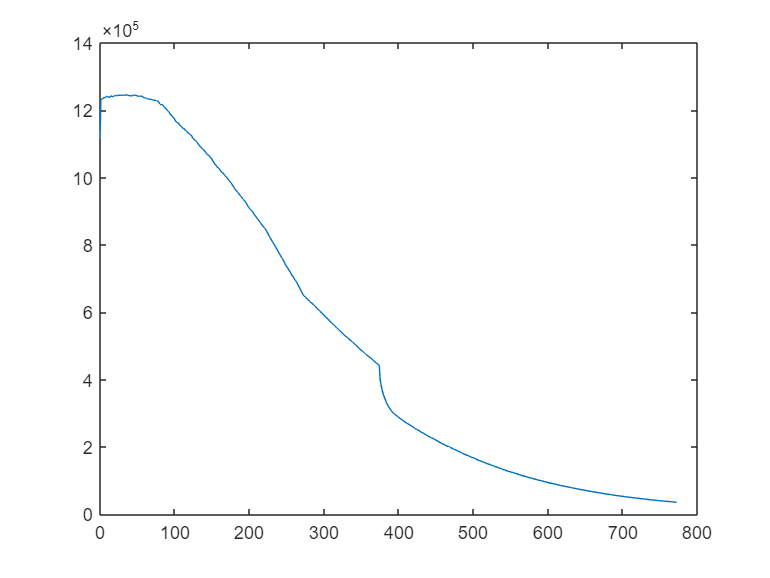

Elapsed time is 1.796644 seconds.


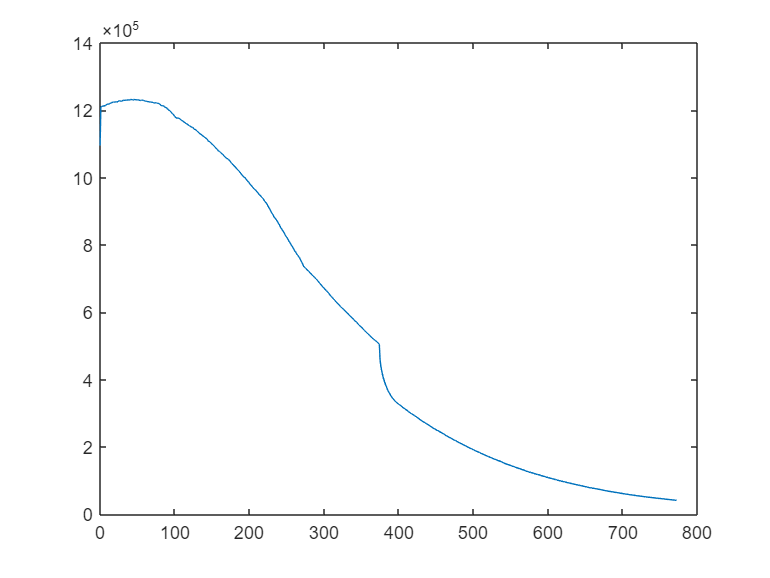

Elapsed time is 1.138756 seconds.


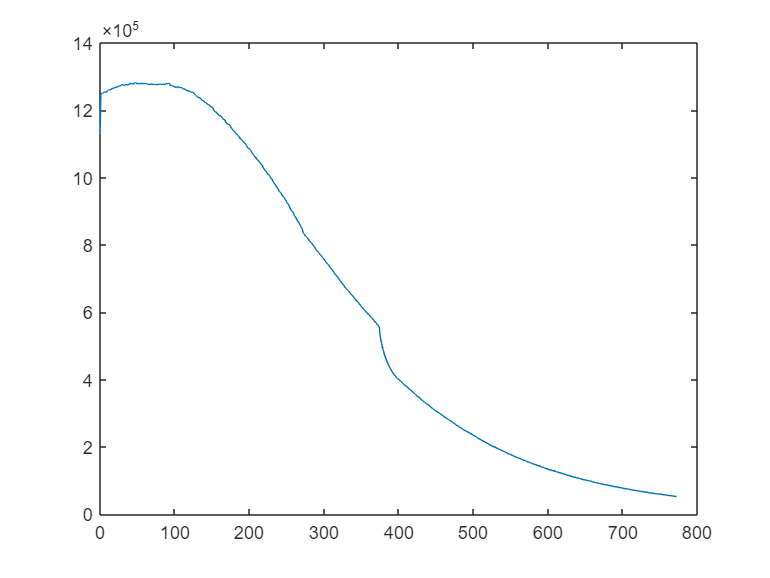

Elapsed time is 2.857420 seconds.


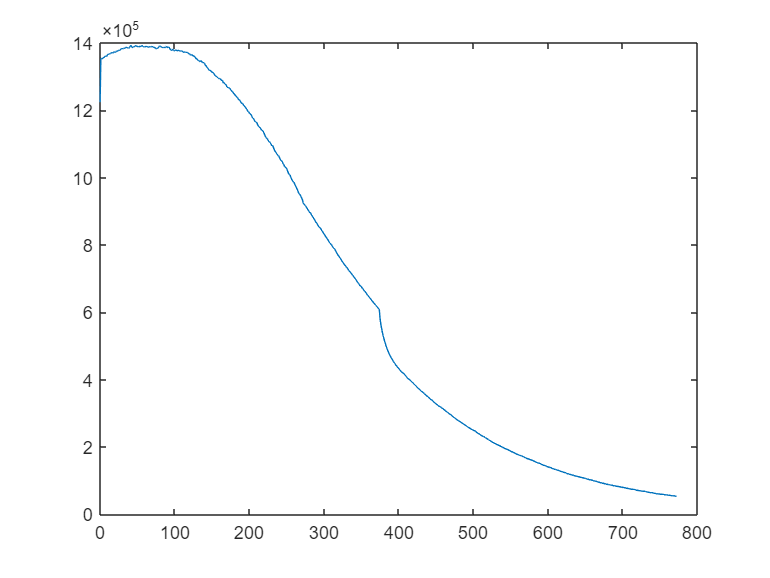

Elapsed time is 1.796458 seconds.


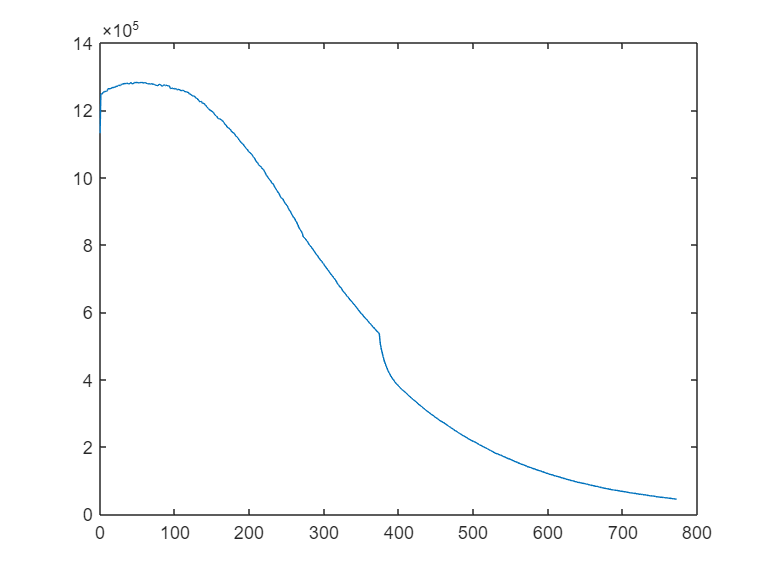

Elapsed time is 1.162509 seconds.


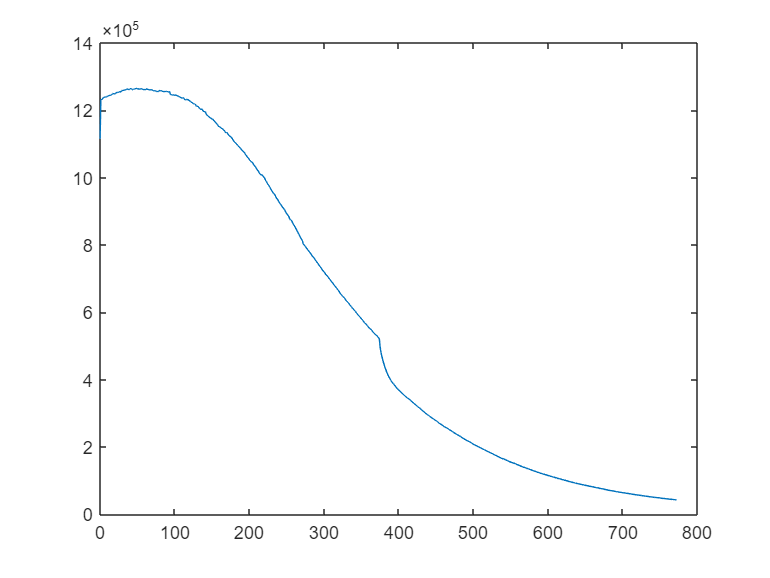

Elapsed time is 1.876854 seconds.


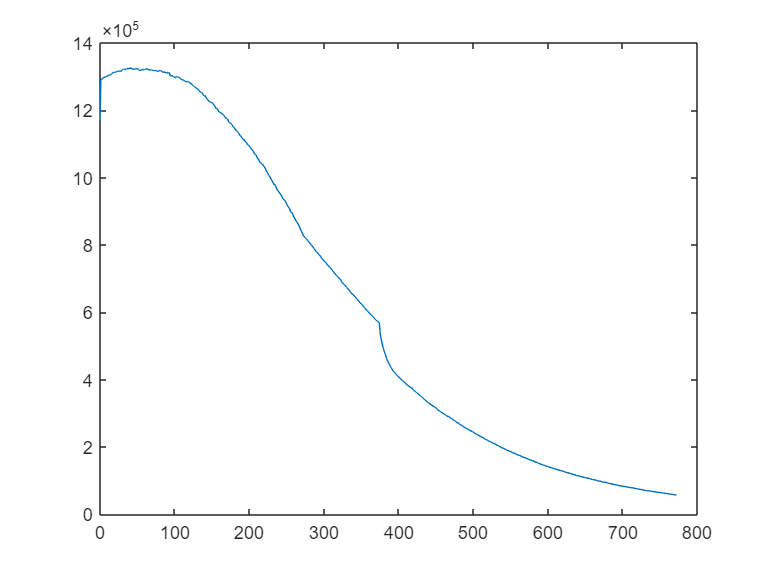

Elapsed time is 3.129533 seconds.


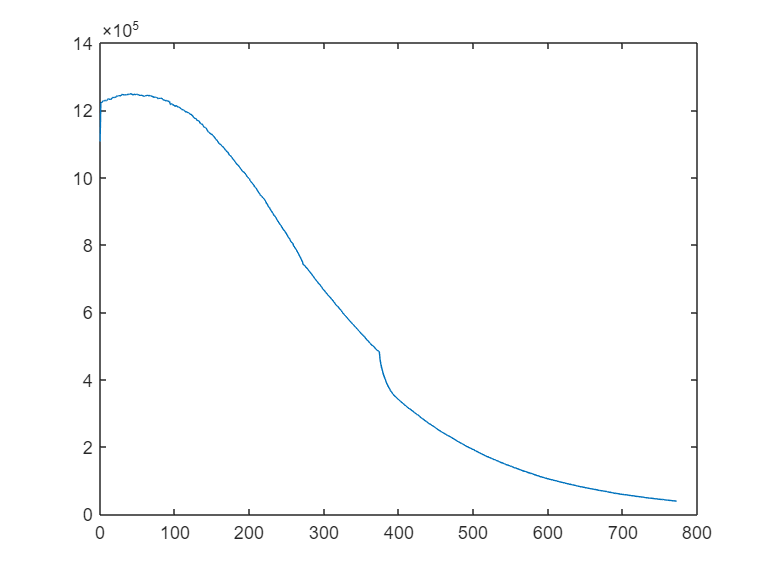

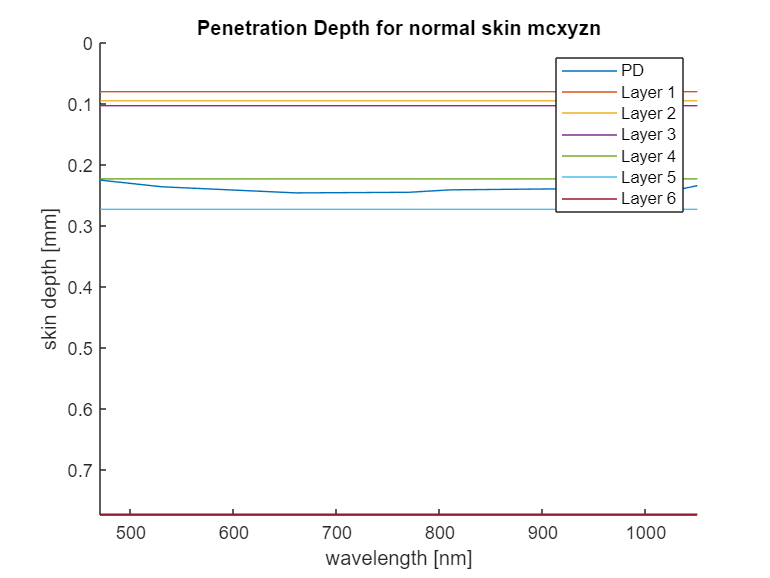

Elapsed time is 0.700743 seconds.


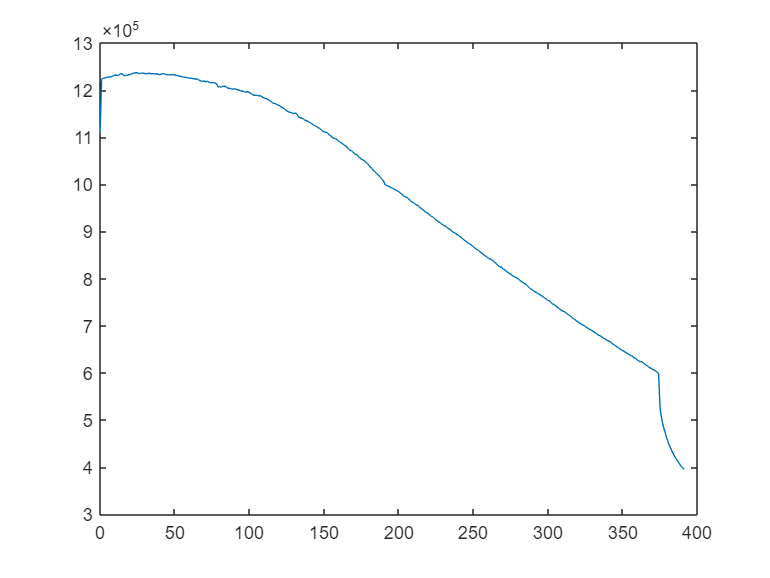

Elapsed time is 0.680184 seconds.


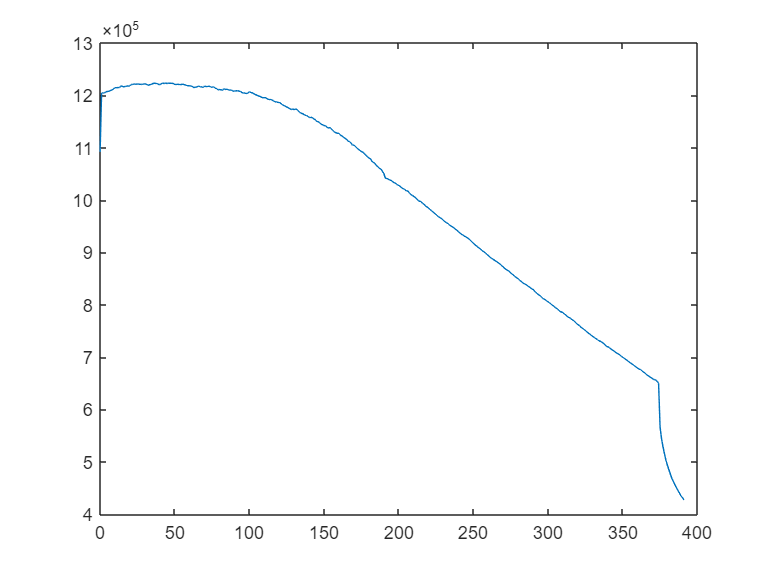

Elapsed time is 0.729240 seconds.


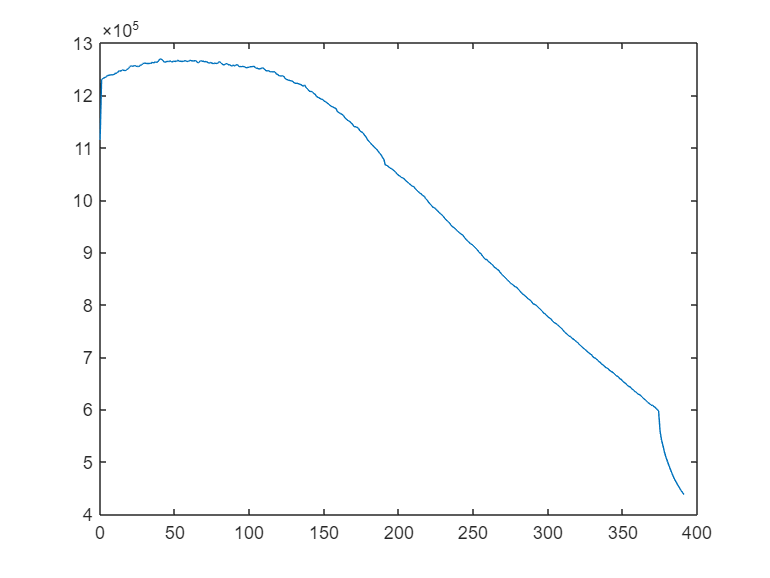

Elapsed time is 1.276937 seconds.


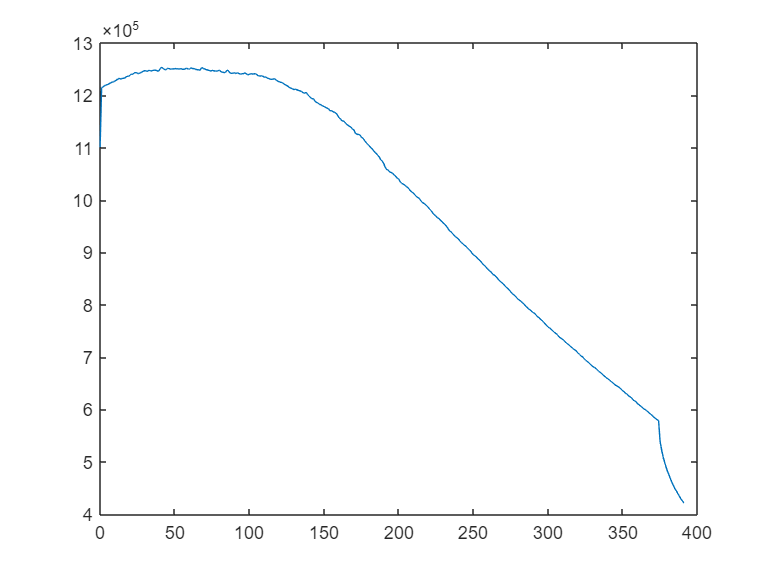

Elapsed time is 0.574017 seconds.


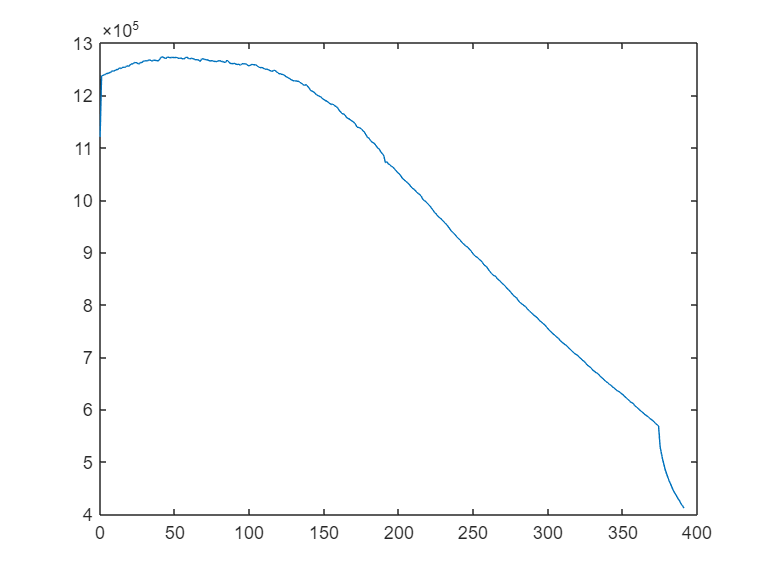

Elapsed time is 0.377180 seconds.


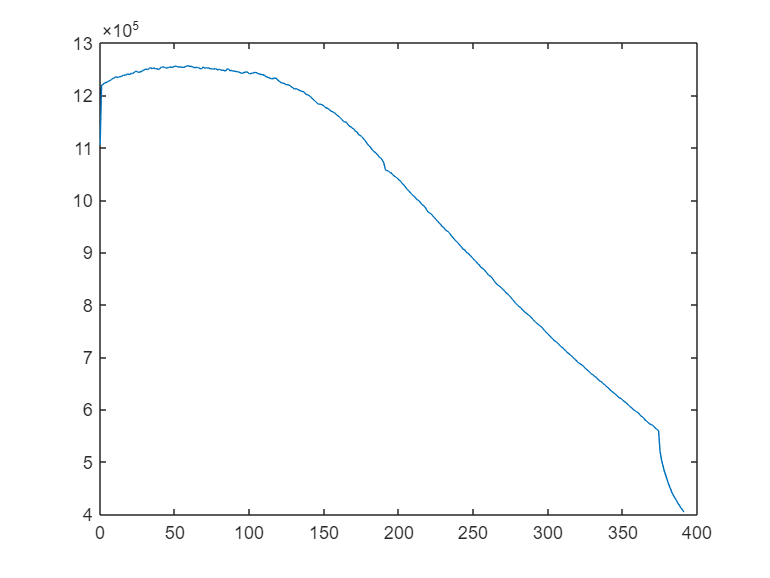

Elapsed time is 0.365803 seconds.


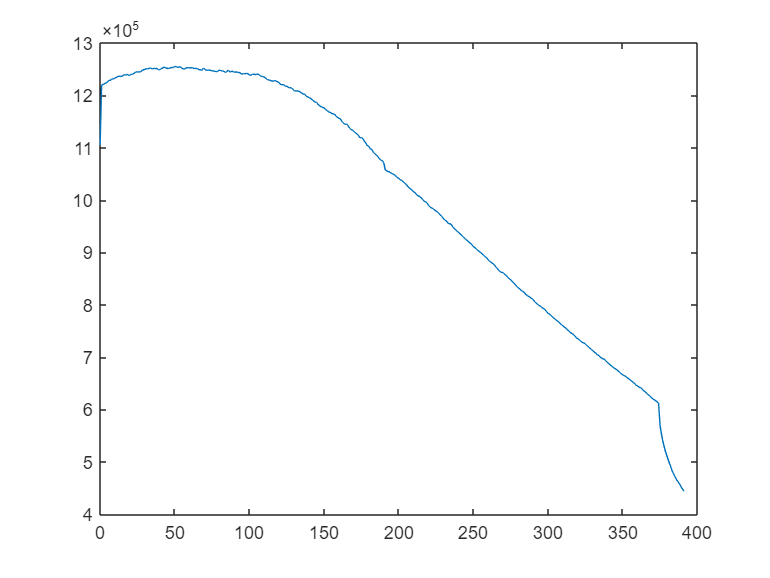

Elapsed time is 0.390039 seconds.


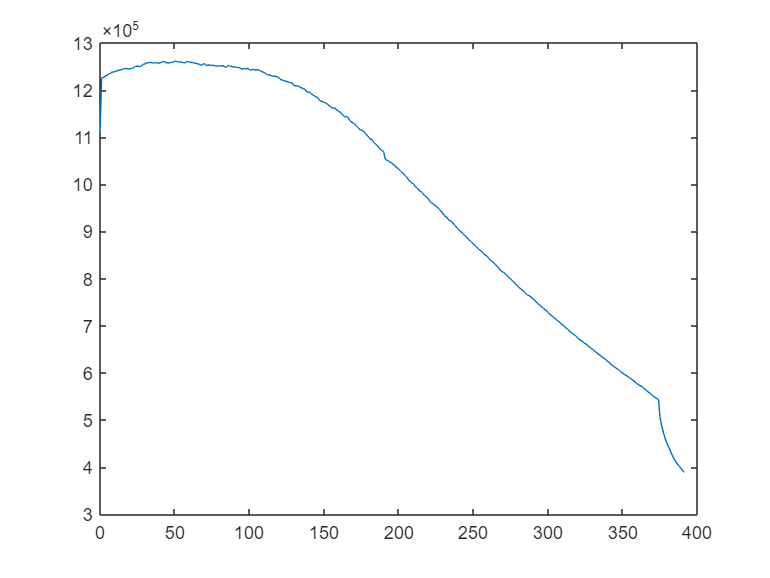

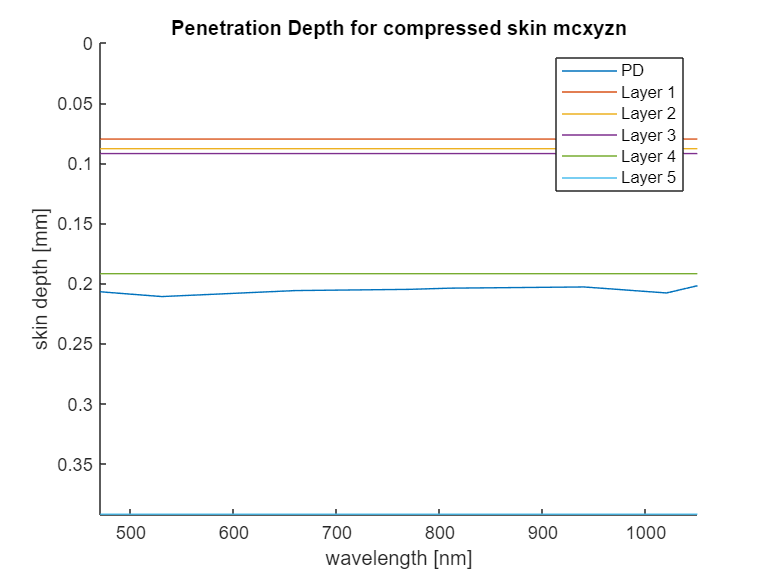

read_fluence_mcxyzn(1,1)

And for the comparison: Here are the original results from moco.